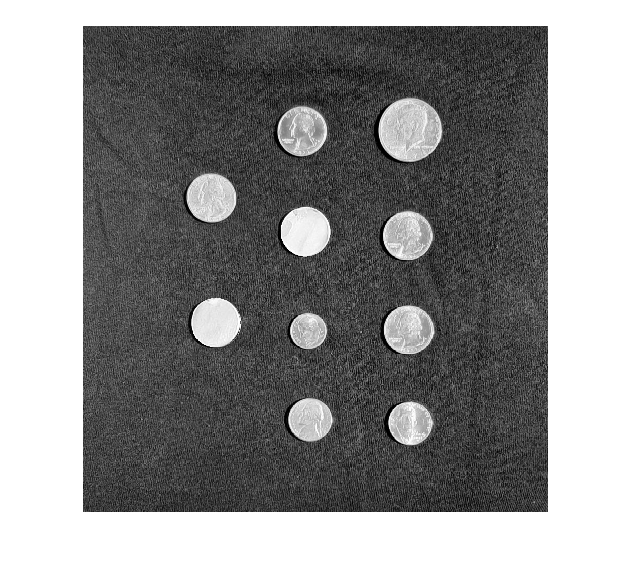

testImageIdx = randi([1,3]);
testCoinImage = imread("testCoinImage"+testImageIdx+".png");
figure,imshow(testCoinImage)

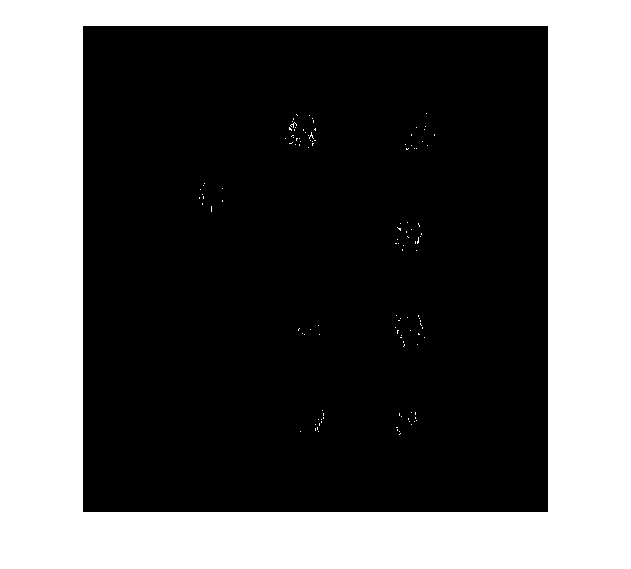


%call segmentation function
[testCoinMask,maskedTestCoin]= segmentImageCoinTest(testCoinImage);
% Shrink the coin mask.
se = strel('disk', 13, 0);
testCoinMask = imfill(testCoinMask, 'holes'); % Fill any holes in it.
testCoinMask = imerode(testCoinMask, se); % Shrink by 3 layers of pixels.

imgFilt = imgaussfilt(maskedTestCoin,0.7,Padding="circular",FilterDomain="frequency",FilterSize=3);
faceEdgeMask= edge(imgFilt,"sobel",0.075,"both");
faceEdgeMask(~testCoinMask) = false;
imshow(faceEdgeMask)